digitDatasetPath = fullfile(matlabroot,'toolbox','nnet','nndemos', ...
'nndatasets','DigitDataset');

imds = imageDatastore(digitDatasetPath, ...
'IncludeSubfolders',true,'LabelSource','foldernames');

% Number of images taken for each class (from 0 to 1000)
numTrainFiles = 200;
[imdsTrain,imdsValidation] = splitEachLabel(imds,numTrainFiles,'randomize');

tr_in = readall(imdsTrain);
tr_tg = imdsTrain.Labels;

tr_tg = 2000×1 categorical array
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 


ts_in = readall(imdsValidation);
ts_tg = imdsValidation.Labels;

plot(tr_tg)

tr_in = 2000×1 cell array
    {28×28 uint8}
    {28×28 uint8}
    {28×28 uint8}
    {28×28 uint8}
    {28×28 uint8}
    {28×28 uint8}
    {28×28 uint8}
    {28×28 uint8}
    {28×28 uint8}
    {28×28 uint8}
    {28×28 uint8}
    {28×28 uint8}
    {28×28 uint8}
    {28×28 uint8}
    {28×28 uint8}
    {28×28 uint8}


omega_b = 0.2;
Nh = 784;
ts = 10000;
f = @(bias, hidden_weights, hidden) tanh(bias + hidden_weights*hidden);
x0 = zeros(Nh,1);
phi = @eulerForward;
eps = 0.001;
eigs = -1000*ones(Nh,1);
ws = 0;
lambda_r = 0.1;
%Nl = 1;
seed = 1;

addpath src

net = NeuralODE(omega_b, Nh, ts, f, phi, eps, eigs, ws, lambda_r, seed);

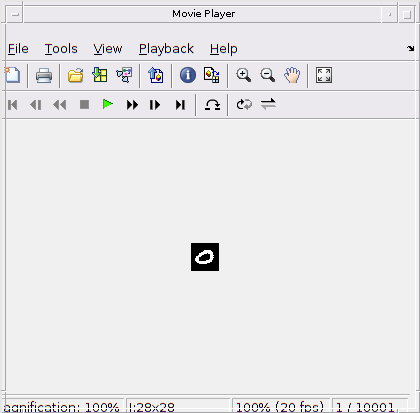

%hidden = net.hiddenState(tr_in);

index_sample = 25;
input_sample = tr_in(index_sample);

hidden_sample = net.hiddenState(input_sample);

% Reshape to sequence of images
hidden_sample = reshape(hidden_sample{:},[sqrt(Nh),sqrt(Nh),size(hidden_sample{:},2)]);

% Play video
implay(hidden_sample)

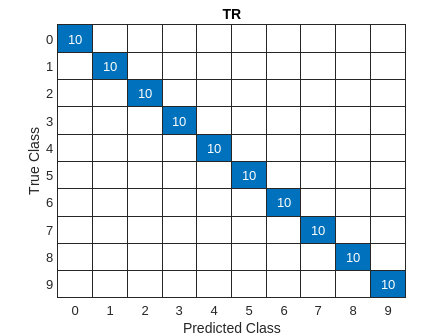

[net,pred_tr]=net.fit(tr_in,tr_tg);
figure
confusionchart(tr_tg, pred_tr);
title("TR")